# Unsupervised Learning

## Load Data (3-4)

Load and display the processed data stored in `processedData.mat`.

load ch2_processedData
disp(head(scFeatures))

                            NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius    RangeAtomicR

Extract the numeric matrix of data from the `superFeatures` table using [`vartype`](matlab: doc vartype)

featureNum = scFeatures(:, vartype("numeric"));
featureData = featureNum.Variables;

Extract the cleaned matrix of numeric data.

featureDataClean = scFeaturesClean{:, vartype("numeric")};

## Correlation Analysis (3-6)

Calculate the correlation between variables using [`corr`](matlab: doc corr). Remember to use the `"rows", "pairwise"` name value pair to use the maximum number of observations when calculating the correlation.

featureCorr = corr(featureData, "rows", "pairwise");

Visualize the correlation matrix with a [`heatmap`](matlab: doc heatmap)`.`

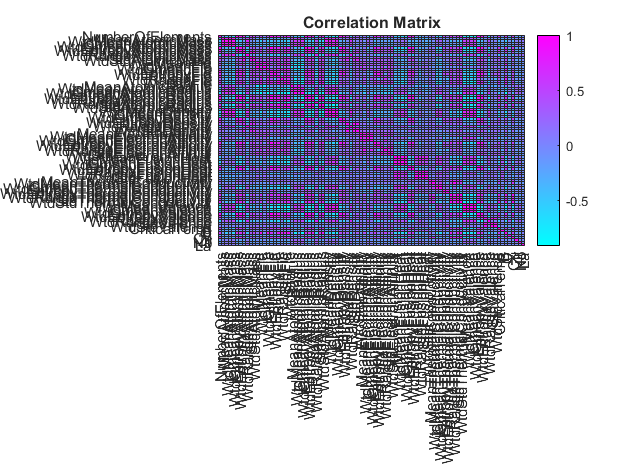

featureNames = string(featureNum.Properties.VariableNames);
heatmap(featureNames, featureNames, featureCorr, "Colormap", cool)
title("Correlation Matrix")

Tabulate the pairs of variables with an absolute correlation greater than 0.95. 

highCorrPairs = triu(abs(featureCorr) > 0.95, 1);
[rIdx, cIdx] = find(highCorrPairs);

highCorrTbl = table(featureNames(rIdx)', featureNames(cIdx)', featureCorr(highCorrPairs), ...
    'VariableNames', ["Variable1", "Variable2", "Correlation"]);
highCorrTbl = sortrows(highCorrTbl, "Correlation", "descend");
disp(highCorrTbl)

            Variable1                      Variable2             Correlation
    __________________________    ___________________________    ___________

    "EntropyFie"                  "EntropyAtomicRadius"            0.99763  
    "WtdMeanValence"              "WtdGmeanValence"                0.99509  
    "WtdMeanFie"                  "WtdGmeanFie"                    0.99273  
    "EntropyFie"                  "EntropyValence"                 0.99251  
    "MeanValence"                 "GmeanValence"                   0.99008  
    "EntropyAtomicRadius"         "EntropyValence"                  0.9896  
    "RangeThermalConductivity"    "StdThermalConductivity"         0.98746  
    "RangeFusionHeat"             "StdFusionHeat"                  0.98452  
    "RangeFie"                    "StdFie"                         0.98203  
    "WtdMeanAtomicRadius"         "WtdGmeanAtomicR

We can see there is signifcant correlations in the data and perhaps not all 85 features are equally informative.  We may be able to eliminate some unecessary information if we can uncover the structure in the data.  To this end we look at PCA which rotates our data in such a way that the directions with the most variation come first.

## Principal Component Analysis (PCA) (3-7)

### Normalizing Data

Create a box plot for each variable.

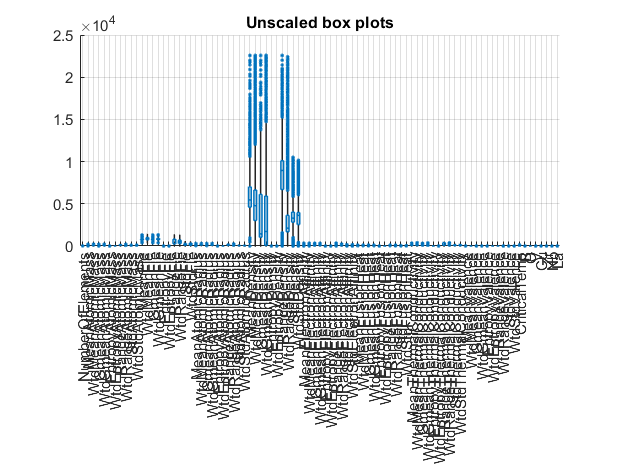

boxchart(featureDataClean, "MarkerStyle", ".")
xticklabels(featureNames)
grid on
title("Unscaled box plots")

Note that some variables are on a different scale. This will bias any results from PCA.

Use [`normalize`](matlab: doc normalize) to rescale the variables, and visualize the box plots.

featureNorm = normalize(featureDataClean);

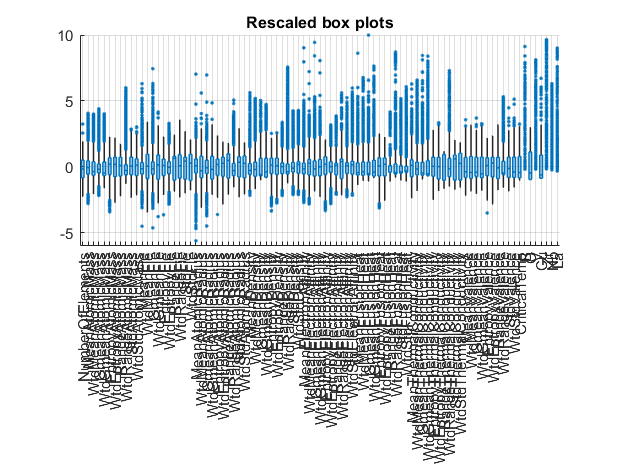

boxchart(featureNorm, "MarkerStyle", ".")
xticklabels(featureNames)
grid on
title("Rescaled box plots")

### Coefficients

Perform [`pca`](matlab: doc pca) on the normalized features. Take five outputs.

[C, S, e, t2, explained] = pca(featureNorm);

The first output is the coefficient matrix. Visualize the first five columns with a heatmap.

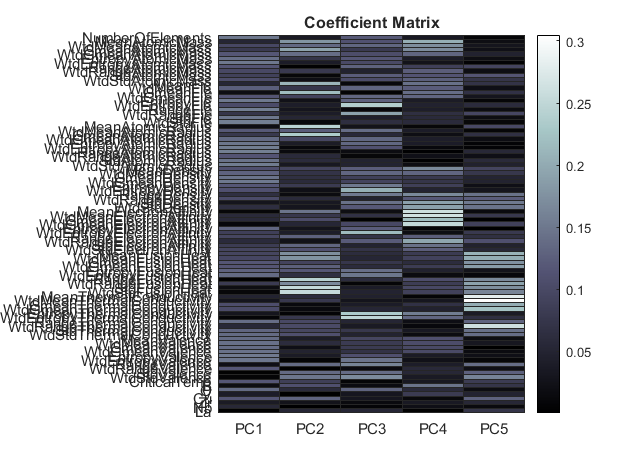

compNames = "PC" + (1:width(C));
heatmap(compNames(1:5), featureNames, abs(C(:, 1:5)), ...
    "Colormap", bone)
title("Coefficient Matrix")

### Scores

The second output are the scores. Visualize the first three components using a [`gplotmatrix`](matlab: doc gplotmatrix)`.`

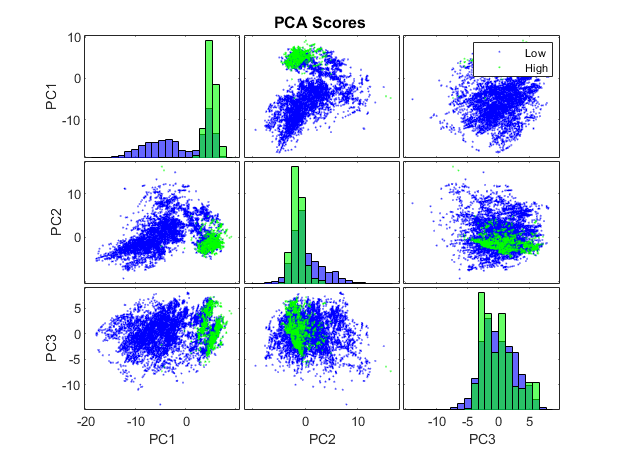

gplotmatrix(S(:, 1:3), [], scFeaturesClean.TcClass, ...
    [], [], [], [], "grpbars", compNames(1:3))
title("PCA Scores")

## Dimensionality Reduction (3-8)

Dimensionality reduction can help remove redundent information from our dataset, and identify key features. This can help reduce complexity when creating predictive models.

### Selecting Components

Create a [`pareto`](matlab: doc pareto) plot of the variance of the principal components using the third output from `pca`.

pareto(e)

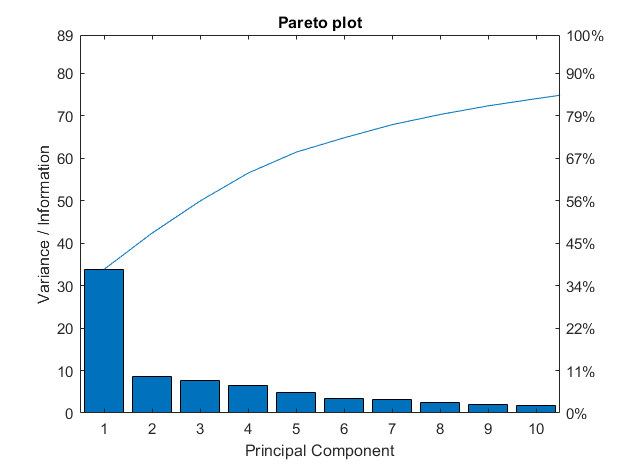

ylabel("Variance / Information")
xlabel("Principal Component")
title("Pareto plot")

Calculate the number of components that make up 95% on the variance/information in the data.

varThresh = 95;
numComponents = find(cumsum(explained) > varThresh, 1)

numComponents = 21

Compare the percentage information to a random dataset of the same size, by plotting the fifth output from `pca`.

[~, ~, ~, ~, ernd] = pca(randn(size(featureNorm)));

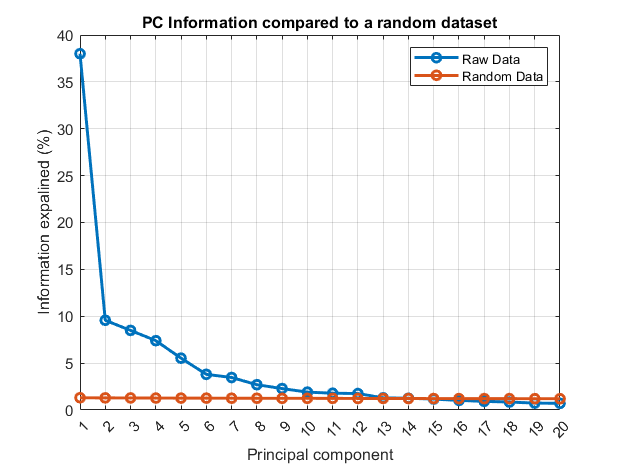

plot(explained, "o-", "LineWidth", 2)
xticks(1:length(ernd))
xlabel("Principal component")
grid on
ylabel("Information expalined (%)")
title("PC Information compared to a random dataset")
hold on
plot(ernd, "o-", "LineWidth", 2)
hold off
legend("Raw Data", "Random Data")
xlim([1 20])

### Selecting Features

Use [`rotatefactors`](matlab: doc rotatefactors) on the coefficient matrix to align the features with a component, and visualize the resulting matrix.

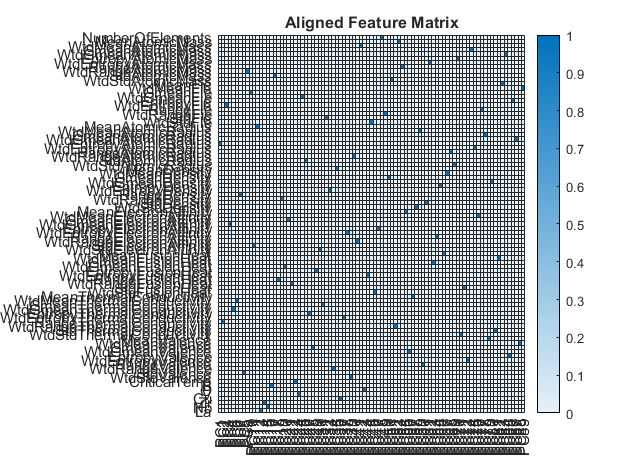

A = rotatefactors(C);
heatmap(compNames, featureNames, abs(A))
title("Aligned Feature Matrix")

Find the features that correspond to the components that make up 95% of information in the data.

[~, impIdx] = max(abs(A));
importantFeatures = featureNames(impIdx(1:numComponents))'

importantFeatures = 21×1 string array
    "EntropyAtomicRadius"
    "RangeThermalConductivity"
    "WtdEntropyFie"
    "WtdGmeanElectronAffinity"
    "WtdGmeanThermalConductivity"
    "WtdMeanThermalConductivity"
    "RangeDensity"
    "StdValence"
    "WtdRangeAtomicMass"
    "GmeanFie"
    "StdElectronAffinity"
    "MeanAtomicRadius"
    "La"
    "Zr"
    "Nb"
    "B"
    "StdAtomicMass"
    "RangeFusionHeat"
    "WtdRangeDensity"
    "WtdGmeanFusionHeat"
    "GmeanElectronAffinity"


## t-Distributed Stochastic Neighborhood Embedding (tSNE) (3-9)

Sample 3000 observations from the normalized features using [`datasample`](matlab: doc datasample)`.`

[featureSample, sampleIdx] = datasample(featureNorm, 3000);

Use [`tnse`](matlab: doc tsne) on the data sample, and visualize the output grouped by critical temperature.

Z = tsne(featureSample);

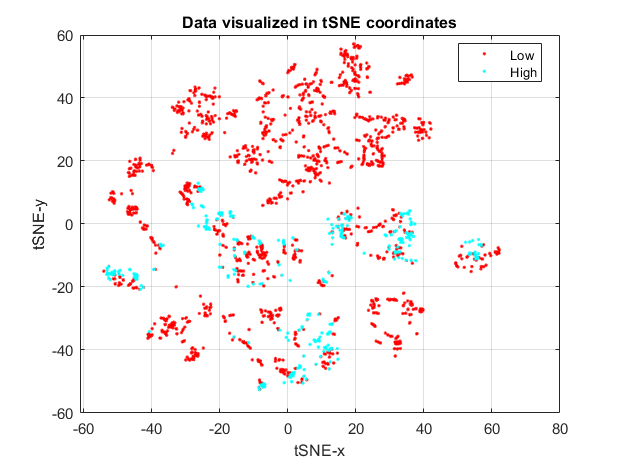

gscatter(Z(:, 1), Z(:, 2), scFeaturesClean.TcClass(sampleIdx))
grid on
title("Data visualized in tSNE coordinates")
xlabel("tSNE-x")
ylabel("tSNE-y")

## Outlier Detection (3-10)

### t-Squared Statistics

The fourth output from `pca` are the $t^2$-statistics for each material. Create a logical array to identify the largest 3% of $t^2$ values using [`prctile`](matlab: doc prctile)`.`

percentOutliers = 3;
t2OutlierIdx = t2 > prctile(t2, 100-percentOutliers);

Confirm that this is a reasonable percentage by visualising the sorted  $t^2$ values.

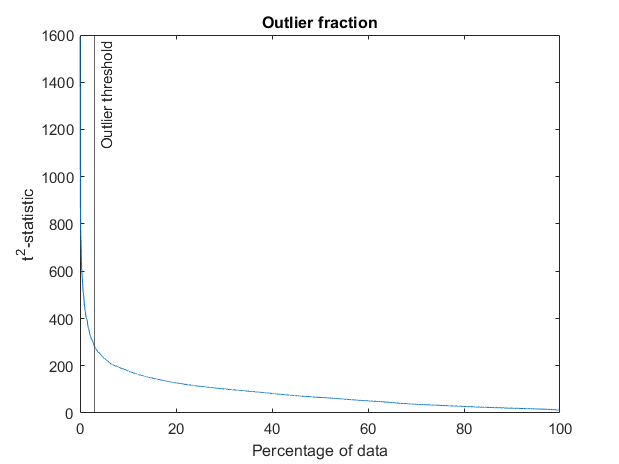

plot((1:length(t2))/length(t2)*100, sort(t2, "descend"))
xlabel("Percentage of data")
ylabel("t^2-statistic")
xline(percentOutliers, "Label", "Outlier threshold")
title("Outlier fraction")

Visualize the data in the first three principal components and highlight the outliers.

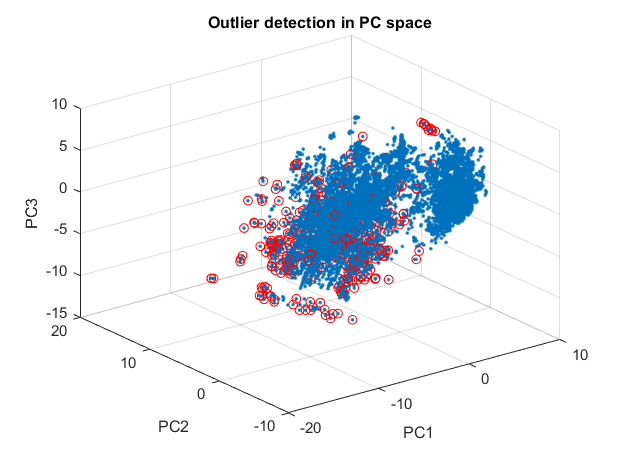

scatter3(S(:, 1), S(:, 2), S(:, 3), ".")
hold on
scatter3(S(t2OutlierIdx, 1), S(t2OutlierIdx, 2), S(t2OutlierIdx, 3), "ro")
hold off
grid on
xlabel(compNames(1))
ylabel(compNames(2))
zlabel(compNames(3))
title("Outlier detection in PC space")

Tabulate the outliers, and display the results.

outlierNames = string(scFeaturesClean.Properties.RowNames(t2OutlierIdx));

outliers = table(outlierNames, t2(t2OutlierIdx), ...
    'VariableNames', ["Material Name","t^2 statistic"]);
outliers = sortrows(outliers, "t^2 statistic", "descend");
disp(outliers)

                 Material Name                  t^2 statistic
    ________________________________________    _____________

    "C60"                                          1591.9    
    "C"                                            1582.3    
    "C70"                                          1582.3    
    "C1"                                             1582    
    "N4H12Na2Cs1C60"                               1408.5    
    "H1Cl3C61"                                     1367.9    
    "O2"                                           1265.7    
    "Ag2F1"                                        1136.8    
    "H1Br3C61"                                     1033.5    
    "Br2"                                          1025.3    
    "Cs1"                                          917.46    
    "Ag2I1"                                        908.15    
    "Ag0.002Al0.998"                               867.46    
 

### Isolation Forest

Using [`iforest`](matlab: doc iforest), create an isolation forest using the scores from PCA, with a  `ContaminationFraction` of $0.03$.

% [~, iforestOutlierIdx] = iforest(S, ...
%     "ContaminationFraction", percentOutliers/100);

Visualize the data in the first three principal components and highlight the outliers.

% scatter3(S(:, 1), S(:, 2), S(:, 3), ".")
% hold on
% scatter3(S(iforestOutlierIdx, 1), S(iforestOutlierIdx, 2), S(iforestOutlierIdx, 3), "ro")
% hold off
% grid on
% xlabel("PC1")
% ylabel("PC2")
% zlabel("PC3")
% title("Outlier detection in PC space")

## k-Means Clustering (3-11)

Create a `Cluster Data` live task to cluster the normalized features using the [`kmeans`](matlab: doc kmeans) algorithm. 

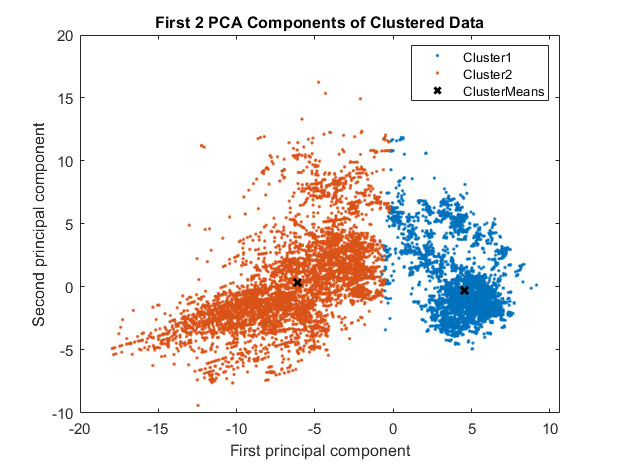

% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[kmeansIdx,kmeansCentroids] = kmeans(featureNorm,K);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(featureNorm);
clusterMeans = grpstats(score,kmeansIdx,"mean");
h = gscatter(score(:,1),score(:,2),kmeansIdx,colormap("lines"));
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## Interpreting Clusters (3-12)

Create a [`parallelcoords`](matlab: doc parallelcoords) (parallel plot) of the normalized features using the $k$-means clustering results.

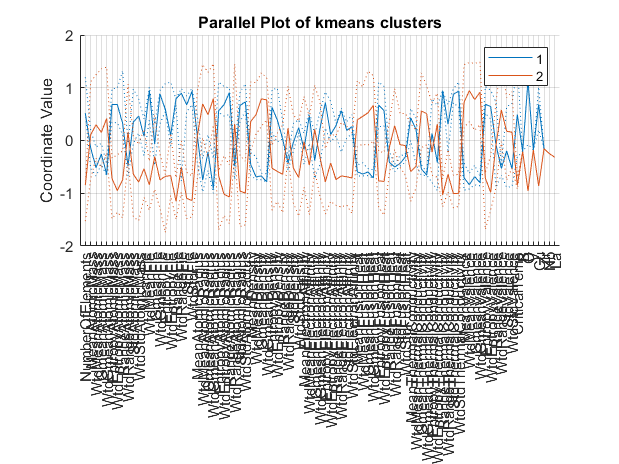

parallelcoords(featureNorm, ...
    "Group", kmeansIdx, ...
    "Quantile", 0.25, ...
    "Labels", featureNames)
title("Parallel Plot of kmeans clusters")
grid on

Recreate the [parallel plot](#M_6DD2AC0B) by reordering the features using the centroid difference.

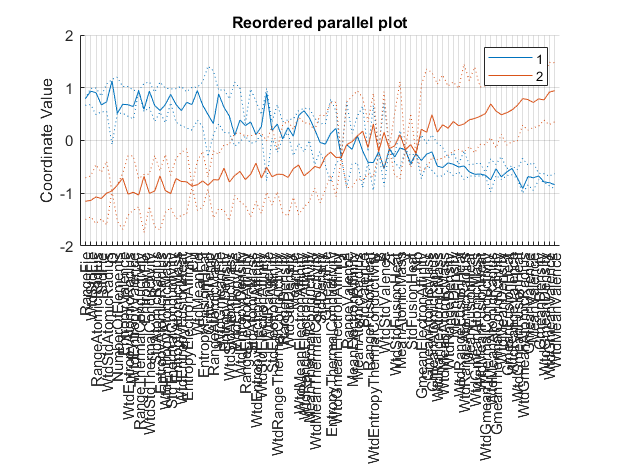

reorderedParallelCoords(featureNorm, kmeansIdx, kmeansCentroids, featureNames);

Using [crosstab](matlab: doc crosstab), visualize the counts of high and low temperature superconductors in each cluster.

kmeansCt = crosstab(scFeaturesClean.TcClass, kmeansIdx);

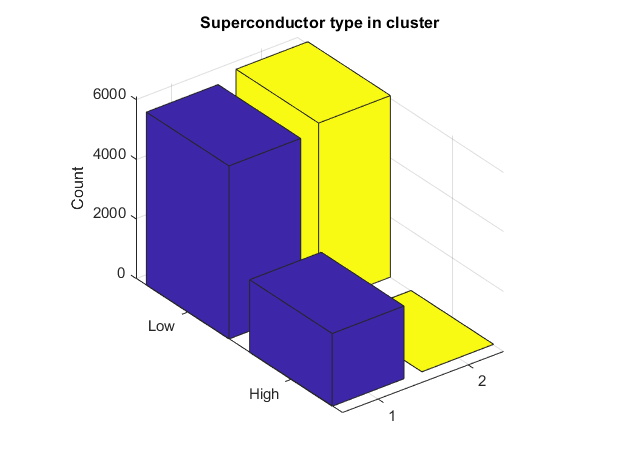

bar3(kmeansCt)
yticklabels(categories(scFeaturesClean.TcClass))
zlabel("Count")
title("Superconductor type in cluster")

## Gaussian Mixture Models (GMM) (3-13)

Fit a guassian mixture model on the superconductor data using [fitgmdist](matlab: doc fitgmdist).

rng default

gmMdl = fitgmdist(S(:, 1:numComponents), 2, "Replicates", 10)

gmMdl = 

Gaussian mixture distribution with 2 components in 21 dimensions




Find the centroid locations.

gmCentroids = gmMdl.mu;

[cluster](matlab: web(fullfile(docroot, 'stats/gmdistribution.cluster.html'))) the data to return the group index for each observation.

[gmIdx, ~, probScore] = cluster(gmMdl, S(:, 1:numComponents));

Visualize the results.

gscatter(S(:, 1), S(:, 2), gmIdx)
grid on
title("GMM Clustering results")
xlabel(compNames(1))
ylabel(compNames(2))
hold on
scatter(gmCentroids(:, 1), gmCentroids(:, 2), 100, "k*", ...
    "DisplayName", "Centroids")

Use the third output from `cluster` to visualize and tabulate materials that have low probability of belonging to any cluster. 

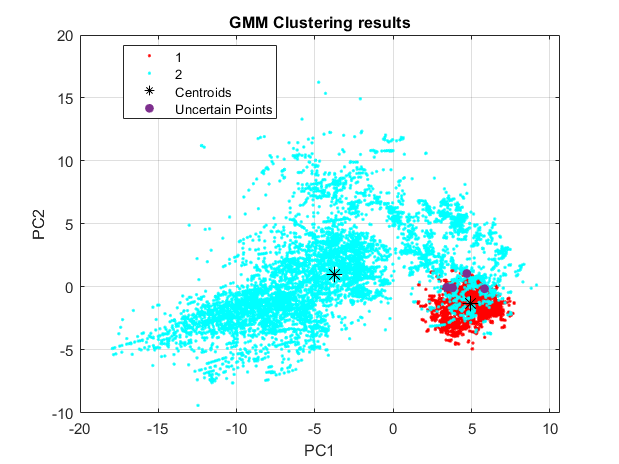

uncertainIdx = all(probScore < 0.75, 2);
scatter(S(uncertainIdx, 1), S(uncertainIdx, 2), "filled", ...
    "DisplayName", "Uncertain Points")
hold off

disp(scFeaturesClean(uncertainIdx, :))

                                       NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius    R

### Interpretation

Visualize the [bivariate histogram](#M_6DD2AC0B) for each cluster.

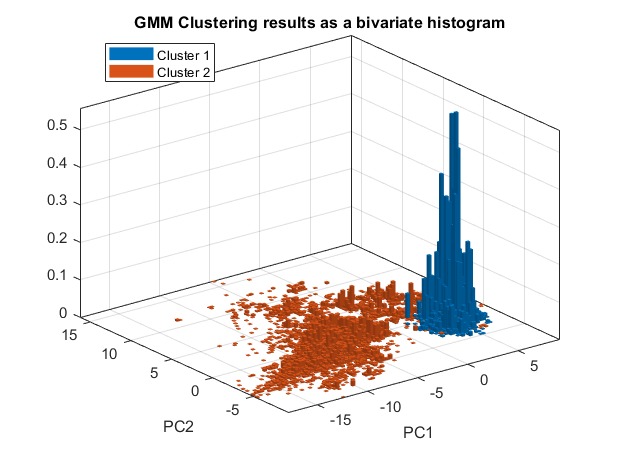

ghistogram2(S, gmIdx, 100);

Calculate the centroid locations in feature space. 

gmmCentroidsFeatures = gmCentroids * C(:, 1:numComponents)';

Visualize the reordered parallel plot.

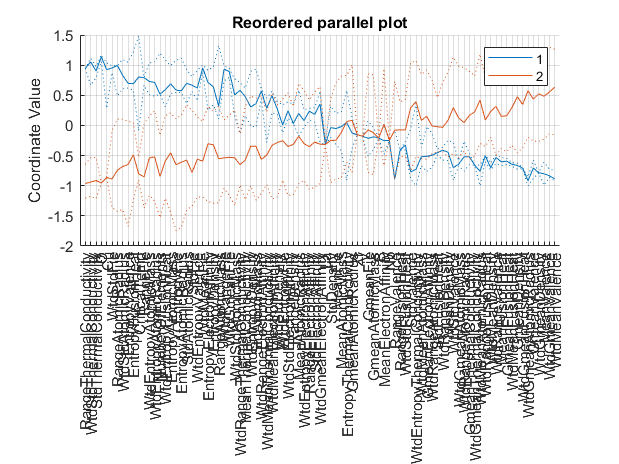

reorderedParallelCoords(featureNorm, gmIdx, gmmCentroidsFeatures, featureNames)

Visualize the counts of high and low temperature superconductors in each cluster.

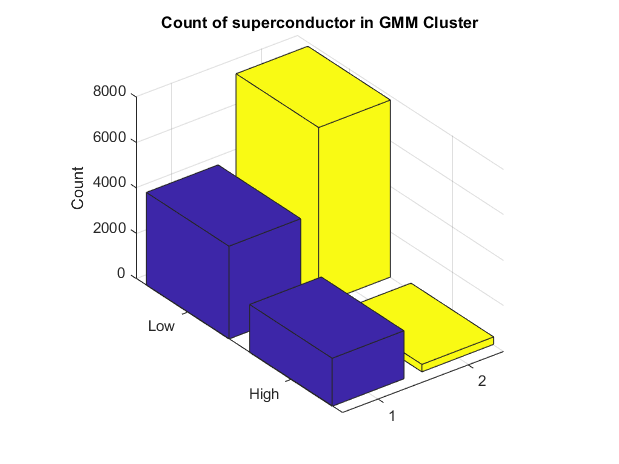

gmmCt = crosstab(scFeaturesClean.TcClass, gmIdx);
bar3(gmmCt)
yticklabels(categories(scFeaturesClean.TcClass))
zlabel("Count")
title("Count of superconductor in GMM Cluster")

## Evaluating the clustering results (3-14)

Run [evalclusters](matlab: doc evalclusters) to determine the optimal number of clusters for each clustering method.

kList = 2:8;
ev = evalclusters(featureNorm, "kmeans", ...
    "DaviesBouldin", "KList", kList);

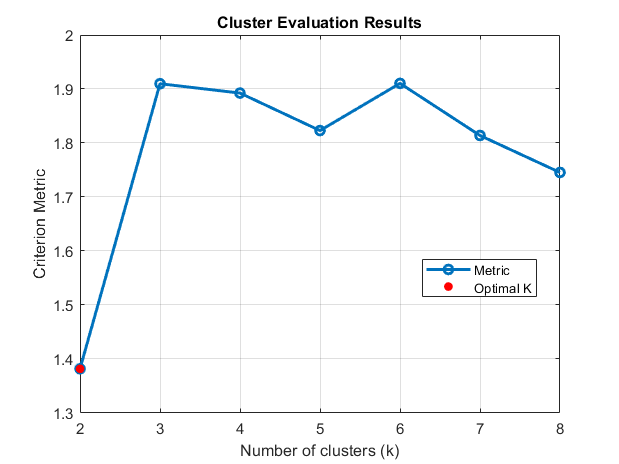

plot(ev.InspectedK, ev.CriterionValues, "o-", "LineWidth", 2)
grid on
xlabel("Number of clusters (k)")
ylabel("Criterion Metric")
title("Cluster Evaluation Results")
optimalIdx = ev.InspectedK == ev.OptimalK;
hold on
scatter(ev.InspectedK(optimalIdx), ev.CriterionValues(optimalIdx), "filled", "ro")
hold off
legend("Metric", "Optimal K", "Location", "best")

## Hierarchical Clustering (3-15)

Calculate the pairwise distance between features using [pdist](matlab: doc pdist).

featureDist = pdist(featureNorm');

Create a hierarchical clustering of features using a [linkage](matlab: doc linkage) of pairwise distances.

featureLinkage = linkage(featureDist, "ward");

Visualize a [dendrogram](matlab: doc dendrogram) of the hierarchical clustering results.

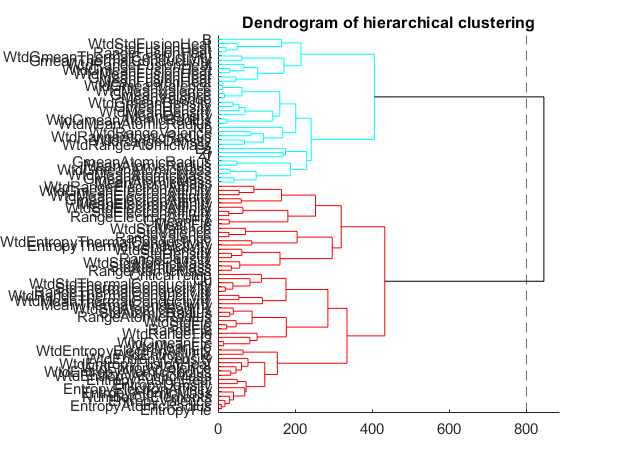

colorThresh = 800;
[~, ~, leafOrder] = dendrogram(featureLinkage, length(featureNames), ...
    "Labels", featureNames, ...
    "Orientation", "right", ...
    "ColorThreshold", colorThresh);
xline(colorThresh, "--")
title("Dendrogram of hierarchical clustering")

## Save results

save clusteredData importantFeatures gmIdx scFeaturesClean t2OutlierIdx

## Local Functions

function ghistogram2(S, gIdx, nBins)
labels = unique(gIdx);
pc1Edges = linspace(min(S(:,1)), max(S(:,1)), nBins);
pc2Edges = linspace(min(S(:,2)), max(S(:,2)), nBins);
figure
for k = labels'
    histogram2(S(gIdx == k, 1), S(gIdx == k, 2), ...
        pc1Edges, pc2Edges, "Normalization", "pdf")
    hold on
end
xlabel("PC1")
ylabel("PC2")
legend("Cluster " + labels, "Location", "best")
title("GMM Clustering results as a bivariate histogram")
end

function reorderedParallelCoords(features, gIdx, centroids, featureNames)
centroidDiff = diff(centroids);
[~, sortIdx] = sort(centroidDiff);
figure
parallelcoords(features(:, sortIdx), ...
    "Group", gIdx, ...
    "Quantile", 0.25, ...
    "Labels", featureNames(sortIdx))
title("Reordered parallel plot")
grid on
end